# Organize and Analyze Training Data

clear vars; close all; clc;
NUM_NODES = 1628;
OUTPUT_NODE = 1354;
MAX_PCA_MODES = 100;
dt = 0.001;
T = 3.0;

% MODIFY THIS: Set parameters
sample_rate = 6; % In milliseconds

% Find closest divisible entry for chosen sampling rate
N = T / dt;
Tspan = linspace(0,T,N);
N_divisible = allDivisors(N);
[~, sample_batch] = min(abs(N_divisible - sample_rate));

## Pick Training Data

[files,path] = uigetfile('*.csv',...
   'Select One or More Files', ...
   'MultiSelect', 'on');

## Consolidate Training Data

% Consolidated data is stored in 'modal_trajectory_data/train_data/output/'
% Make sure to unzip all trajectory csv files into
% 'modal_trajectory_data/train_data/'
[filePath, xData] = consolidateData(path, files, Tspan, ...
    NUM_NODES, sample_batch, 'storeType', 'both');

Load Data:  000%  |                                          | 0/6it [00:00:00<Inf:NaN:NaN, Inf it/s]


## PCA on Consolidated Data

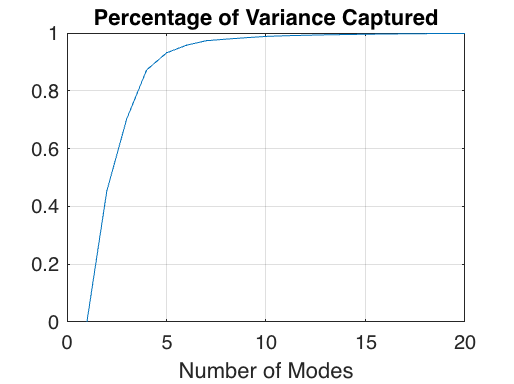

% Modify this - change last entry for the mat file you want to PCA
fileForPCA = append(path, 'output/', 'qvConsolidatedData.mat');

xPCA = importdata(fileForPCA);
[V, S] = PCA(xPCA, MAX_PCA_MODES);

maxNumModes = 20;
modes = linspace(1, maxNumModes, maxNumModes);
energyFunc = @(x) sum(S(x:end).^2) / sum(S.^2);

figure;
plot(modes, 1 - arrayfun(energyFunc, modes));
grid on;
title('Percentage of Variance Captured');
xlabel('Number of Modes');